# **Ejemplos de Procesos**

Autor: Juan Parras

Asignatura: SALT

**Ejemplo 1: proceso sencillo**

Sea un proceso de tiempo discreto $X\left\lbrack n\right\rbrack$, donde, por comodidad, sólo representaremos los primeros 10 instantes de tiempo. El siguiente simulador nos permite visualizar realizaciones de este proceso, donde podemos elegir (1) la distribución de primer orden del proceso, $f_X \left(x;n\right)$, y (2) si queremos que todas las variables sean de la misma distribución

En primer lugar, comencemos visualizando un proceso sencillo: toma tiempo para entender la función realizar_proceso (al final de este script), que usamos para generar el proceso. 

n = 10;  % Longitud del proceso (en tiempo)
r = 3;  % Número de realizaciones del proceso

dist_primer_orden = ["Bernoulli", "Binomial", "Poisson", "Uniforme", "Exponencial", "Gaussiana"];

seleccionar_dist = "Gaussiana";

if seleccionar_dist == "Aleatoria"
    dist_list = dist_primer_orden(randi(length(dist_primer_orden), [1, n]));
else
    dist_list = repmat(seleccionar_dist, [1, n]);
end

disp("La lista de distribuciones es: ")

La lista de distribuciones es: 


dist_list'  % Distribución de cada instante de tiempo (recuerda que cada X[n] es una v.a.)

ans = 10×1 string array
    "Gaussiana"
    "Gaussiana"
    "Gaussiana"
    "Gaussiana"
    "Gaussiana"
    "Gaussiana"
    "Gaussiana"
    "Gaussiana"
    "Gaussiana"
    "Gaussiana"


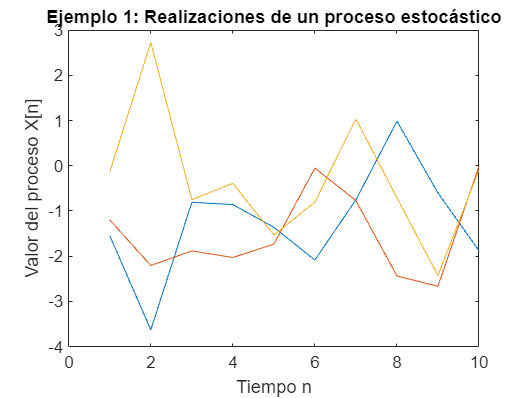


proceso = realizar_proceso(n, r, dist_list);


% Ahora mostramos las realizaciones del proceso
plot(1:n, proceso')
ylabel('Valor del proceso X[n]')
xlabel('Tiempo n')
title('Ejemplo 1: Realizaciones de un proceso estocástico')

**Ejemplo 2: media, desviación típica, autocorrelación y autocovarianza del proceso**

La media y la desviación típica de un proceso son funciones del tiempo: para cada valor de tiempo, tenemos la media / desviación típica de las variable aleatoria $X\left\lbrack n\right\rbrack$

n = 10;  % Longitud del proceso (en tiempo)
r = 100;  % Número de realizaciones del proceso

dist_primer_orden = ["Bernoulli", "Binomial", "Poisson", "Uniforme", "Exponencial", "Gaussiana"];

seleccionar_dist = "Aleatoria";

if seleccionar_dist == "Aleatoria"
    dist_list = dist_primer_orden(randi(length(dist_primer_orden), [1, n]));
else
    dist_list = repmat(seleccionar_dist, [1, n]);
end

disp("La lista de distribuciones es: ")

La lista de distribuciones es: 


dist_list'  % Distribución de cada instante de tiempo (recuerda que cada X[n] es una v.a.)

ans = 10×1 string array
    "Bernoulli"
    "Bernoulli"
    "Bernoulli"
    "Gaussiana"
    "Uniforme"
    "Uniforme"
    "Poisson"
    "Uniforme"
    "Uniforme"
    "Gaussiana"


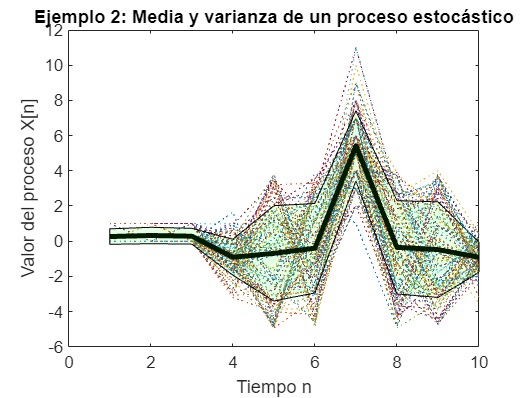


% También podemos mostrar las realizaciones, junto con la media y la
% varianza empíricas del proceso (de cada variable del proceso)
proceso = realizar_proceso(n, r, dist_list);
media_proceso = mean(proceso, 1);  % 1 es la dimensión sobre la que realizamos la media!
std_proceso = std(proceso, 1);

plot(1:n, proceso', ':')  % Plot de cada realización del proceso (el línea de puntos)
hold on
plot(1:n, media_proceso, 'k', 'LineWidth',3)  % Plot de la media del proceso
% Para ver la desviación típica, usamos el siguiente comando, que nos pinta
% el área entre media - std y media + std
patch([1:n fliplr(1:n)], [media_proceso - std_proceso fliplr(media_proceso + std_proceso)], 'g', "FaceAlpha", 0.1)
hold off
ylabel('Valor del proceso X[n]')
xlabel('Tiempo n')
title('Ejemplo 2: Media y varianza de un proceso estocástico')

Como se observa, la intuición es sencilla:

- La media del proceso $\eta_X \left\lbrack n\right\rbrack$ nos muestra la evolución de la media de cada v.a. $X\left\lbrack n\right\rbrack$ que compone el proceso. Es una medida de centralidad del proceso. 

- La desviación típica del proceso $\sigma_X \left\lbrack n\right\rbrack$ refleja la dispersión de los valores del proceso respecto a la media.

Pasemos a calcular la autocorrelación y autocovarianza del proceso (empíricas), $R_X \left\lbrack n_1 ,n_2 \right\rbrack$ y $C_X \left\lbrack n_1 ,n_2 \right\rbrack$. Como son funciones de dos variables (dos instantes de tiempo), representarlas es un poco difícil, salvo que fijemos un tiempo. En nuestro caso, fijaremos $n_1$, con lo cual estaremos calculando cuánto se parece cada variable del proceso a la variable aleatoria $X\left\lbrack n_1 \right\rbrack$

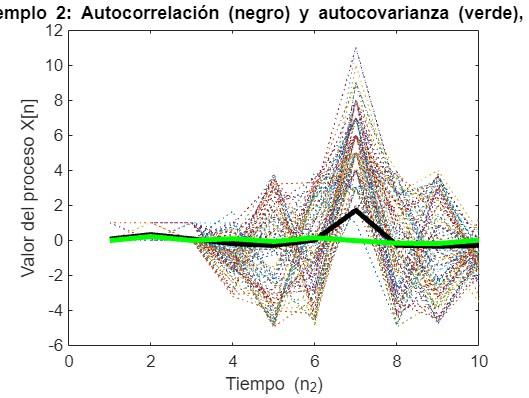

n1 = 2;
autocorrelacion = zeros(n, 1);
for n2=1:n
    autocorrelacion(n2) = mean(proceso(:,n1) .* proceso(:, n2));
end
autocovarianza = autocorrelacion' - media_proceso(n1) * media_proceso;

plot(1:n, proceso', ':')  % Plot de cada realización del proceso (el línea de puntos)
hold on
plot(1:n, autocorrelacion, 'k', 'LineWidth',3)
plot(1:n, autocovarianza, 'g', 'LineWidth',3)
hold off
ylabel('Valor del proceso X[n]')
xlabel('Tiempo (n_2)')
title(['Ejemplo 2: Autocorrelación (negro) y autocovarianza (verde), n_1=', num2str(n1)])

Es importante observar cómo la autocorrelación y la autocovarianza representan la información de "semejanza" del proceso:

- Fijado $n_1$, la autocorrelación y autocovarianza son grandes en $n_2 =n_1$, porque es la semejanza de una variable aleatoria consigo misma.

- Para $n_1 \not= n_2$, la autocorrelación tomará valores altos si la variable $X\left\lbrack n_2 \right\rbrack$ se parece a $X\left\lbrack n_1 \right\rbrack$, y bajos en caso contrario (esto se ve más claramente seleccionando "Aleatoria" en la distribución de primer orden del proceso). La autocovarianza tenderá a cero, debido a que cada $X\left\lbrack n\right\rbrack$ es independiente, y por tanto, incorrelado, para $n_1 \not= n_2$.

**Ejemplo 3: rampa de ordenada en el origen aleatoria**

Implementación del problema que aparece en las transparencias, comprobando los resultados analíticos con los empíricos.

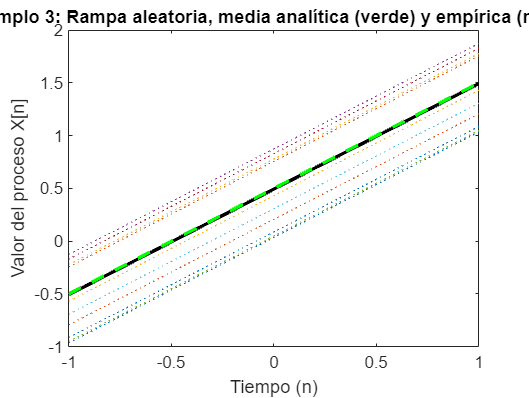

a = 1;  % Valor de la pendiente
t_min = -1; % Tiempo mínimo para visualizar
t_max = 1; % TIempo máximo para visualizar
t_step = 0.01; % Resolución temporal
t = t_min: t_step : t_max;  % Variable de tiempo
r = 100; % Número de realizaciones del proceso

proceso = zeros(r, length(t));

for realizacion=1:r
    y = random('Uniform', 0, 1, 1, 1);
    proceso(realizacion, :) = a*t + y;
end
media_proceso = mean(proceso, 1);
% Mostramos 10 realizaciones del proceso, junto con la media analítica y la
% media empírica
plot(t, proceso(1:10,:)', ':');
hold on
plot(t, media_proceso, 'k', 'LineWidth',2);  % Media empírica
plot(t, a*t + 0.5, 'g', 'LineWidth', 2, 'LineStyle','--'); % Media analítica
hold off
ylabel('Valor del proceso X[n]')
xlabel('Tiempo (n)')
title('Ejemplo 3: Rampa aleatoria, media analítica (verde) y empírica (negro)')

Para representar la autocorrelación $R_X \left(t_1 ,t_2 \right)=a^2 t_1 t_2 +\frac{a\left(t_1 +t_2 \right)}{2}+\frac{1}{3}$, al igual que en el ejemplo anterior, fijamos $t_1$ para facilitar la representación

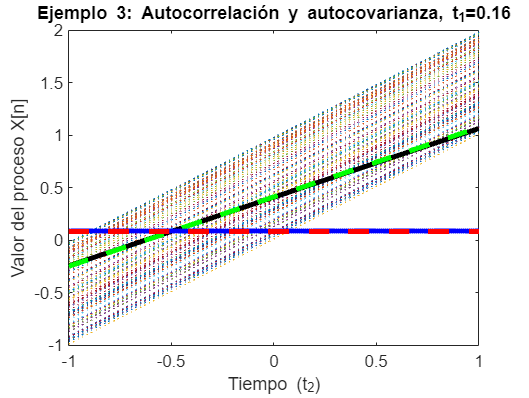

t1 = 0.16;
autocorrelacion = zeros(length(t), 1);

[~, t1_idx] = min(abs(t1-t)); % A diferencia de los ejemplos 1 y 2, ahora t NO es el índice de tiempo!
for t2_idx=1:length(t)
    autocorrelacion(t2_idx) = mean(proceso(:,t1_idx) .* proceso(:, t2_idx));
end

autocovarianza = autocorrelacion' - media_proceso(t1_idx) * media_proceso;

plot(t, proceso', ':')  % Plot de cada realización del proceso (el línea de puntos)
hold on
plot(t, autocorrelacion, 'k', 'LineWidth',3)
plot(t, a^2*t1*t + a * (t1 + t)/2 + 1/3, 'g', 'LineWidth', 3, 'LineStyle', '--')
plot(t, autocovarianza, 'b', 'LineWidth',3)  
plot(t, 1/12 * ones(length(t),1), 'r', 'LineWidth',3, 'LineStyle', '--') 
hold off
ylabel('Valor del proceso X[n]')
xlabel('Tiempo (t_2)')
title(['Ejemplo 3: Autocorrelación y autocovarianza, t_1=', num2str(t1)])

Este proceso presenta $r_X \left(t_1 ,t_2 \right)=1$, por lo que es **linealmente predecible**. 

En el extremo opuesto está los ruidos blancos estrictos, que son **totalmente impredecibles**, como el siguiente ruido blanco estricto gaussiano:

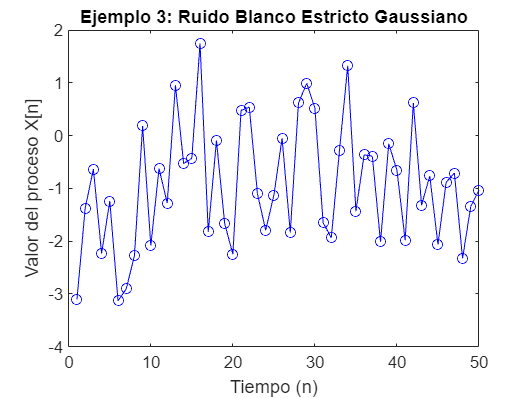

n = 50; % Índice de tiempo
proceso = realizar_proceso(1, n, repmat("Gaussiana", [1, n]));

plot(1:n, proceso', 'ob-');
ylabel('Valor del proceso X[n]')
xlabel('Tiempo (n)')
title('Ejemplo 3: Ruido Blanco Estricto Gaussiano')

Finalmente, recordemos que sólo en el caso gaussiano se cumple que incorrelación implica independencia. En general, esto no es cierto, y por tanto, un ruido blanco no tiene por qué ser un ruido blanco estricto.

**Ejemplo 4: Dos procesos estacionarios en sentido amplio**

Vamos a representar los dos ejemplos de las transparencias. 

Comencemos con el Ruido Blanco Binario, cuyos estadísticos hemos calculado en teoría ($\eta {\;}_X =0,R_X \left\lbrack m\right\rbrack =C_X \left\lbrack m\right\rbrack =\delta \;\left\lbrack m\right\rbrack$) y hemos comprobado que es un proceso estacionario en sentido amplio. Podemos representar el proceso para ver que, efectivamente, esto es correcto:

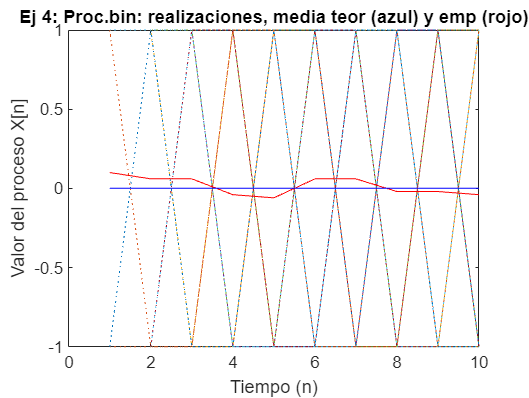

n = 10;  % Número de muestras a obtener del proceso
r = 100;  % Número de realizaciones del proceso a obtener

proceso = zeros(r, n);
for realizacion = 1:r
    for tiempo = 1:n
        u = rand(1);  % Número uniforme entre 0 y 1
        if u > 0.5
            proceso(realizacion, tiempo) = 1;
        else
            proceso(realizacion, tiempo) = -1;
        end
    end
end

media_proceso = mean(proceso, 1);  % Calculamos la media del proceso

% Visualizamos las realizaciones del proceso y la media, tanto la empírica
% como la teórica
plot(1:n, proceso', ':')  % Plot de cada realización del proceso (el línea de puntos)
hold on
plot(1:n, media_proceso, 'r');
plot(1:n, zeros(n, 1), 'b');
hold off
ylabel('Valor del proceso X[n]')
xlabel('Tiempo (n)')
title('Ej 4: Proc.bin: realizaciones, media teor (azul) y emp (rojo)')

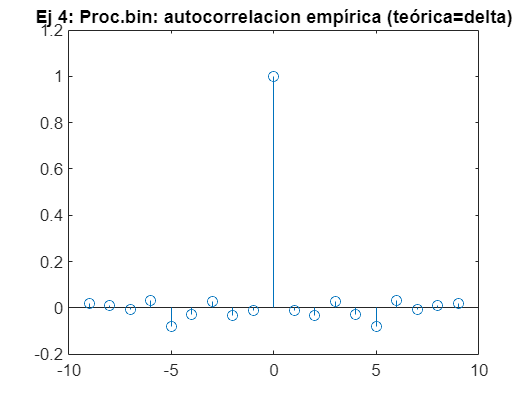


% Como sabemos que es un proceso estacionario, podemos calcular su
% correlación usando la función xcorr de MatLAB.
correlacion = zeros(1, 2*n-1);
tiempo = zeros(1, 2*n-1);
for realizacion = 1:r
    [c, t] = xcorr(proceso(realizacion, :), 'unbiased');
    correlacion = correlacion + c / r; % Al dividir por r, obtenemos una media
    tiempo = tiempo + t / r;
end
stem(tiempo, correlacion);
title('Ej 4: Proc.bin: autocorrelacion empírica (teórica=delta)')

El segundo proceso que hemos visto en teoría es un tono de fase aleatoria: calculemos su distribución de primer orden, así como sus estadísticos, y comprobemos si se ajustan a los teóricos.

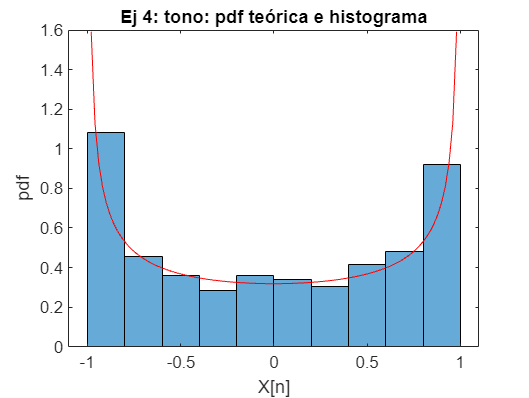

a = 1;  % Amplitud del tono
f = 1;  % Frecuencia del tono
t = linspace(-1, 1, 100);  % Tiempo en el que vamos a obtener los valores
r = 1000;  % Número de realizaciones del proceso

proceso = zeros(r, length(t));
for realizacion = 1:r
    fase = random('Uniform', -pi, pi, 1, 1);
    proceso(realizacion, :) = a * cos(2 * pi* f * t + fase);
end

% Primero, comprobamos la fdp del proceso, elegimos un instante de tiempo
% cualquiera para ello (por ejemplo, el primero)
histogram(proceso(:, 1), 10, 'normalization', 'pdf');
hold on;
plot(linspace(-a, a, 100), 1./(pi*sqrt(a^2-linspace(-a, a, 100).^2)), 'r');
hold off
xlabel('X[n]')
ylabel('pdf')
title('Ej 4: tono: pdf teórica e histograma')

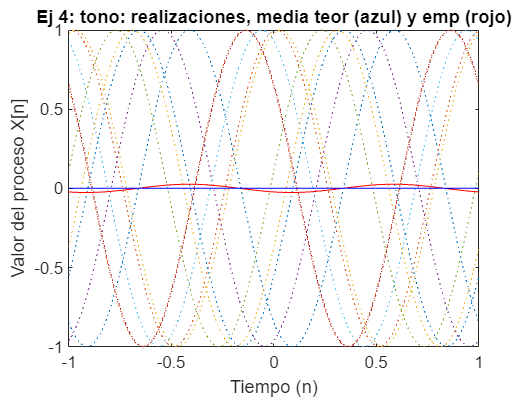


media_proceso = mean(proceso, 1);  % Calculamos la media del proceso
% Visualizamos las realizaciones del proceso y la media, tanto la empírica
% como la teórica
plot(t, proceso(1:10, :)', ':')  % Plot de cada realización del proceso (el línea de puntos)
hold on
plot(t, media_proceso, 'r');
plot(t, zeros(length(t), 1), 'b');
hold off
ylabel('Valor del proceso X[n]')
xlabel('Tiempo (n)')
title('Ej 4: tono: realizaciones, media teor (azul) y emp (rojo)')

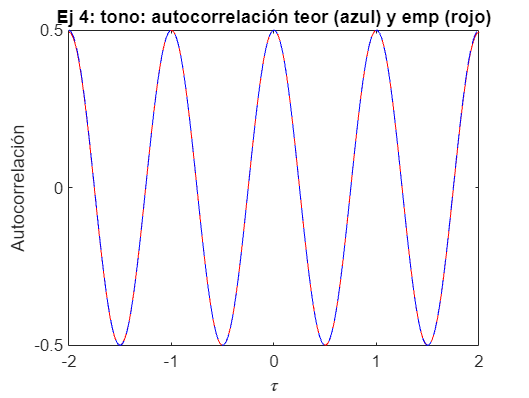


% Como sabemos que es un proceso estacionario, podemos calcular su
% correlación usando la función xcorr de MatLAB.
correlacion_proceso = zeros(1, 2*length(t)-1);
tiempo_c = zeros(1, 2*length(t)-1);
for realizacion = 1:r
    [c, tc] = xcorr(proceso(realizacion, :), 'unbiased');
    correlacion_proceso = correlacion_proceso + c / r; % Al dividir por r, obtenemos una media
    tiempo_c = tiempo_c + tc / r;
end

tau = tiempo_c * (t(2)-t(1)); % Cuidado: MatLAB devuelve tiempos discretos, hay que pasarlo a tiempo continuo en este caso 
plot(tau, correlacion_proceso, 'r');
hold on
plot(tau, a^2/2*cos(2*pi*f*tau), 'b--');
hold off
xlabel('\tau')
ylabel('Autocorrelación')
title('Ej 4: tono: autocorrelación teor (azul) y emp (rojo)')

**Ejemplo 5: Realización, autocorrelación y densidad espectral de potencia en un proceso estacionario en sentido amplio**

Vamos a estudiar la relación entre la autocorrelación, la densidad espectral de potencia (DEP) y las realizaciones en un proceso estacionario en sentido amplio: aparecen varias dualidades:

- Entre las realizaciones y la autocorrelación: autocorrelaciones muy estrechas indican que el proceso es muy poco predecible en el tiempo (o "ruidoso"), mientras que una autocorrelación ancha indica lo contrario. 

- Entre la autocorrelación y la DEP: una autocorrelación ancha indica una DEP estrecha (baja frecuencia), y viceversa. Esta es la explicación para la dualidad del punto previo, ya que una DEP ancha indica que hay alta frecuencia, esto se traduce en una autocorrelación estrecha, y las realizaciones son "ruidosas" en el sentido de ser poco predecibles, es decir, presentan mucha alta frecuencia (variabilidad).

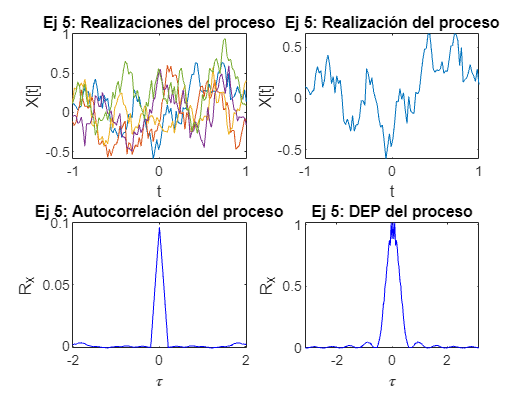

t = linspace(-1, 1, 100);  % Tiempo en el que vamos a obtener los valores
cr = 10;  % Control sobre la correlación del proceso
r = 1000;
% Generamos procesos que tenga correlación (veremos más adelante por qué
% se hace filtrando)
proceso_correlado = zeros(r, length(t));
for realizacion = 1:r
    proceso_blanco = randn(length(t), 1);
    proceso_correlado(realizacion, :) = conv(proceso_blanco, ones(1,cr)/cr, 'same'); % Filtro paso-bajo
end

% Ahora, calculamos la correlación
correlacion_proceso = zeros(1, 2*length(t)-1);
tiempo_c = zeros(1, 2*length(t)-1);
for realizacion = 1:r
    [c, tc] = xcorr(proceso_correlado(realizacion, :), 'unbiased');
    correlacion_proceso = correlacion_proceso + c / r; % Al dividir por r, obtenemos una media
    tiempo_c = tiempo_c + tc / r;
end

subplot(2,2,1)
plot(t, proceso_correlado(1:5, :))
xlabel('t')
ylabel('X[t]')
title('Ej 5: Realizaciones del proceso')

subplot(2,2,2)
plot(t, proceso_correlado(1, :))
xlabel('t')
ylabel('X[t]')
title('Ej 5: Realización del proceso')

subplot(2,2,3)
tau = tiempo_c * (t(2)-t(1)); % Cuidado: MatLAB devuelve tiempos discretos, hay que pasarlo a tiempo continuo en este caso 
plot(tau, correlacion_proceso, 'b');
xlabel('\tau')
ylabel('R_X')
title('Ej 5: Autocorrelación del proceso')

subplot(2,2,4)
f=linspace(-pi, pi, 2*length(t)-1);
psd = abs(fft(correlacion_proceso));  % Empieza en frecuencia 0
% Nota: en teoría, la PSD es real, pero al estimar la correlación, no sale
% perfectamente simétrica, de ahí que haya que aplicar un abs()
plot(f, [psd(length(t):end), psd(1:length(t)-1)], 'b');
xlabel('\tau')
ylabel('R_X')
title('Ej 5: DEP del proceso')


% Calculamos las potencias del proceso: podemos hacerlo con la correlacion
% o la DEP, y el resultado es igual (con ligeras variaciones por trabajar
% con muestras)
potencia_corr = correlacion_proceso(length(t))

potencia_corr = 0.0964

potencia_dep = trapz(f, psd)/(2*pi)  % trapz es la integral numérica (aproximada)

potencia_dep = 0.0924

function [proceso] = realizar_proceso(n, r, dist_list)
    % Esta función genera un proceso independiente, con n valores
    % temporales, donde cada X[n] sigue la distribución especificada en
    % dist_list, y donde r es el número de realizaciones

    proceso = zeros(r,n);  % Para almacenar los valores

    for realizacion = 1:r
        for tiempo = 1:n
            switch dist_list(tiempo)
                case "Bernoulli"
                    proceso(realizacion, tiempo) = random('Binomial', 1, 0.3, 1, 1); % La Bernoulli se genera a través de la Binomial
                case "Binomial"
                    proceso(realizacion, tiempo) = random('Binomial', 10, 0.3, 1, 1);
                case "Poisson"
                    proceso(realizacion, tiempo) = random('Poisson', 5, 1, 1);
                case "Uniforme"
                    proceso(realizacion, tiempo) = random('Uniform', -5, 4, 1, 1);
                case "Exponencial"
                    proceso(realizacion, tiempo) = random('Exponential', 1, 1, 1);
                case "Gaussiana"
                    proceso(realizacion, tiempo) = random('Normal', -1, 1, 1, 1);
                otherwise
                    disp("Distribución no encontrada")
            end
        end
    end
end